%% Clear temporary variables
clear variables

# 2D Exemple - Categorical field - Sand dune training image of Allard et al. (2011)

This figure presents the results of a three-color classification of sand dunes in the Gobi Desert. The probabilities of each class appearing in the reference image are as follows: 42.74% for Facies 1 (black), 26.22% for Facies 2 (gray), and 31.04% for Facies 3 (white). The spatial pattern exhibits an asymmetry oriented from the southwest to the northeast. Along this axis, the most frequent sequence of transitions is 1–2–3, while other sequences occur with significantly lower likelihood.

**Loading and Displaying the Sand Dune Training Image**

This section of the code is responsible for loading and visualizing the sand dune training image. It begins by loading the image data from a specified `.mat` file (`TI_dunes.mat`) containing the sand dune patterns.

Next, the dimensions of the image are obtained using the `size` function, which provides the number of rows (`nx`) and columns (`ny`). A new figure is created to display the image using the `imagesc` function, which visualizes the image data as a scaled color representation. The color bar is added to indicate the scale of the image values, and the colormap is set to gray for improved visualization of the dunes. To enhance contrast, the color limits are adjusted to range from 1 to 3, and the Y-axis direction is set to normal, ensuring the image is oriented correctly.

Finally, the 2D image is reshaped into a one-dimensional vector (`Z`) to facilitate subsequent analyses. A 2D grid is generated using the `grille2` function, providing a spatial framework that corresponds to the dimensions of the sand dune image. This preparation is crucial for further geostatistical analyses of the categorical data within the image.

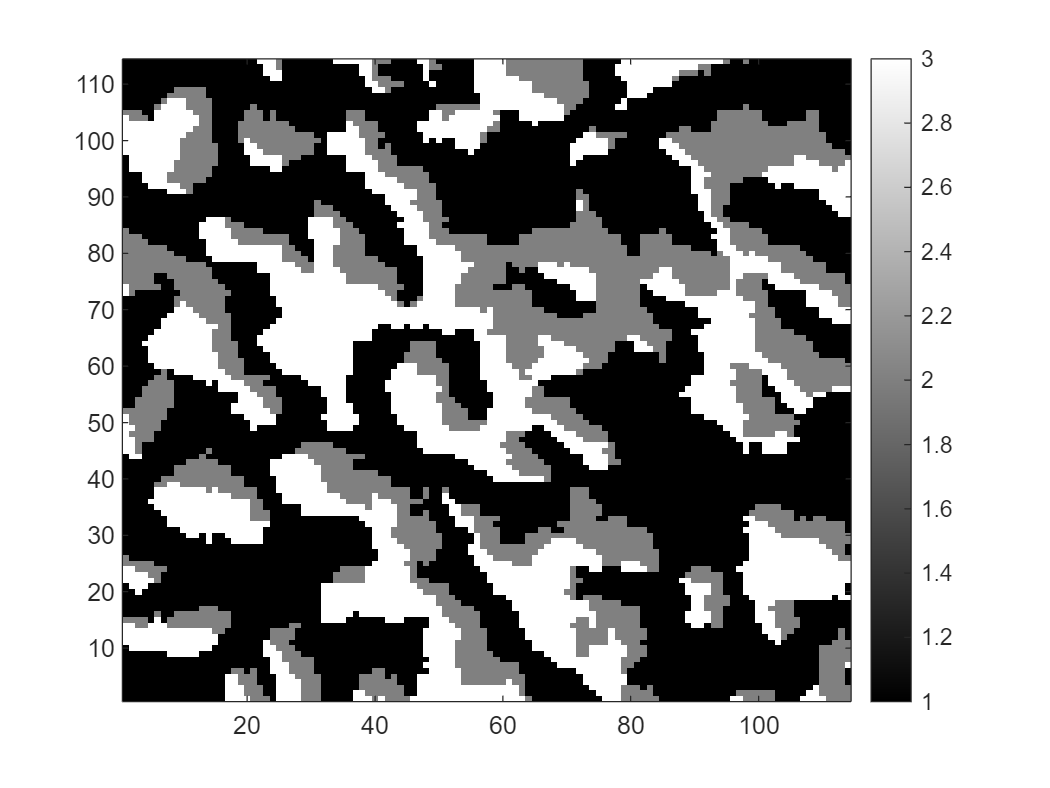

% Load the training image
load('E2 - Dunes/TI_dunes.mat') % Load the sand dune training image from the specified .mat file.

%% Image Size
[nx, ny] = size(ti); % Get the dimensions of the image.

% Display the image
figure(8) % Create a new figure for displaying the image.
imagesc(ti) % Display the image data as a scaled color image.
colorbar() % Add a color bar to indicate the scale of the image.
colormap 'gray' % Set the colormap to gray for better visualization of the dunes.
clim([1 3]) % Set the color limits for the display to enhance contrast.
set(gca,'YDir','normal') % Set the Y-axis direction to normal for correct image orientation.


% Reshape to a vector
Z = reshape(ti,[],1); % Reshape the 2D image into a vector for further analysis.

%% Generate a 2D grid
x0 = grille2(1,nx,1,1,ny,1); % Generate a 2D grid based on the image dimensions.


## Compute the transiogram for categorical data

In this section, the transiogram for categorical data is computed to analyze spatial relationships between different categories within the dune field. The variable `categ` is set to 1 to indicate that the data is categorical, and the `display` flag is activated to visualize the results of the computation. The variable `icode` is set to 6, which specifies the operation for computing transiograms using the GeoStatFFT function. 

The transiogram data is plotted in black for each subplot. Each subplot is labeled with a title indicating which categories are being compared, and the axes are labeled for clarity. This visualization helps in understanding how the spatial continuity of categorical data varies with distance, facilitating the analysis of the relationships among different categories in the dataset.

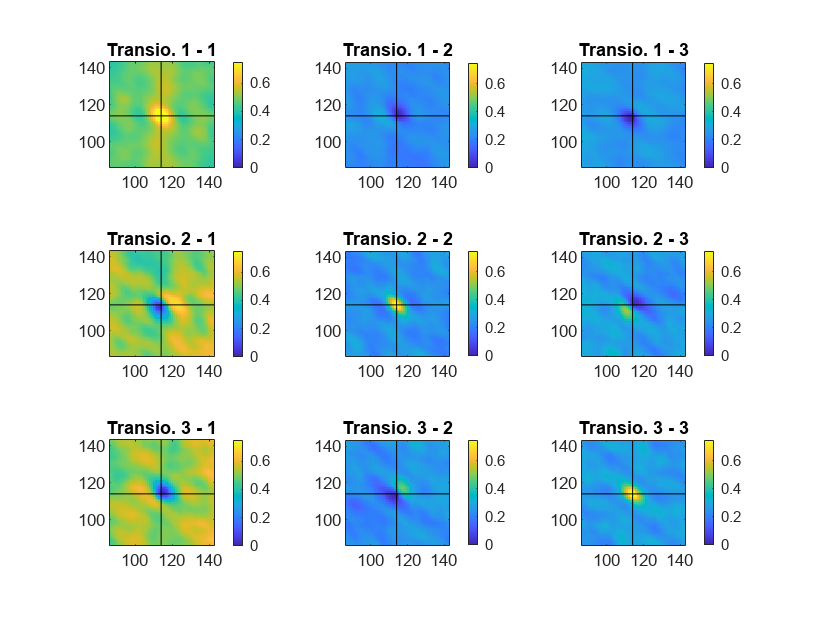

categ = 1; % Specify that the data is categorical.
display = 1; % Set display flag to true to visualize the results.
icode = 6; % Set the code for computing transiograms.

% Compute the transiogram using GeoStatFFT
[gh, nh] = GeoStatFFT(x0, Z, icode, categ, display); 

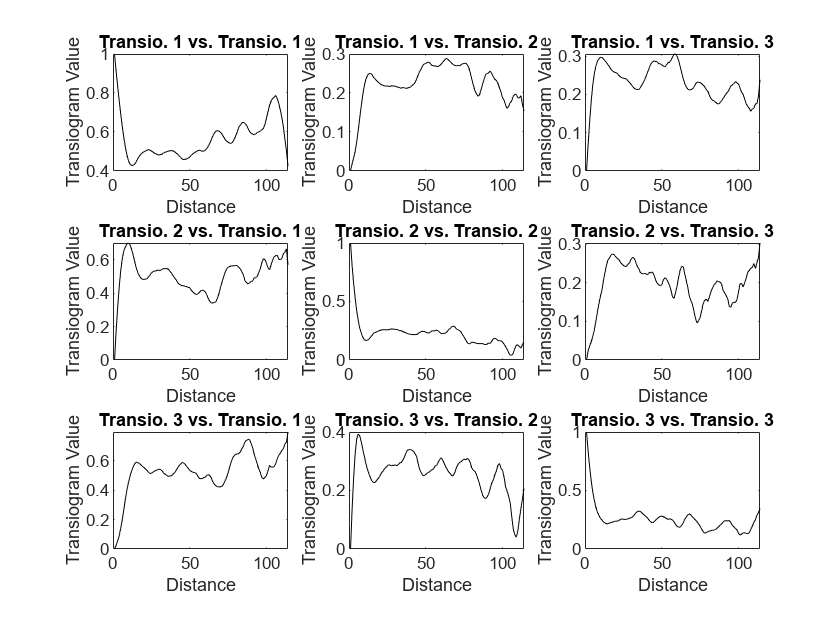


% Plot the transiograms
figure(2) % Create a new figure for plotting transiograms.
for i = 1:3 % Loop through the first dimension (3 categories).
    for j = 1:3 % Loop through the second dimension (3 categories).
        subplot(3, 3, ((i-1)*3 + j)) % Create a subplot for each combination of categories.
        plot(gh{i, j}(nx:end, ny), '-k') % Plot the transiogram data for the current category combination.
        title(['Transio. ' num2str(i) ' vs. Transio. ' num2str(j)]); % Add title for clarity.
        xlabel('Distance'); % Label the x-axis.
        ylabel('Transiogram Value'); % Label the y-axis.
    end
end

## Bivariate probabilities for categorical data

In this section, bivariate probabilities are computed for the categorical data derived from the sand dune training image. The code begins by specifying that the data is categorical (`categ = 1`). The display flag is set to true (`display = 1`), allowing for visualization of the results. The `icode` is defined as 5, which corresponds to the computation of bivariate probabilities.

The bivariate probabilities are visualized in a single figure (figure 4). A nested loop iterates through the three categories, creating subplots for each combination of categories. Each subplot displays the corresponding bivariate probability data plotted in black. This visualization aids in understanding the interactions and dependencies between different categorical classes within the sand dune classification, allowing for further analysis of spatial relationships in the dataset.

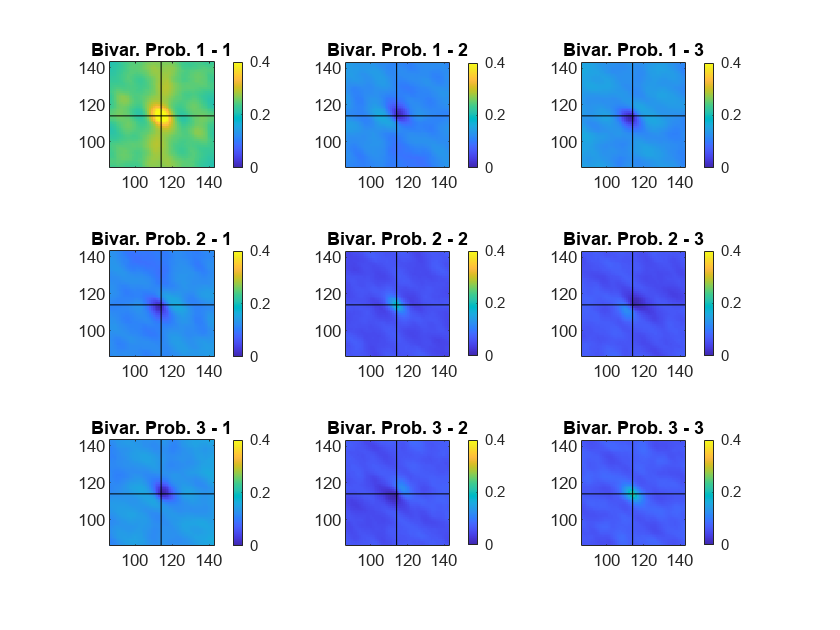

categ = 1; % Specify categorical data.
display = 1; % Set display flag to true for visualization.
icode = 5; % Set the code for computing bivariate probabilities.
[gh, nh] = GeoStatFFT(x0, Z, icode, categ, display); % Compute bivariate probabilities using GeoStatFFT.

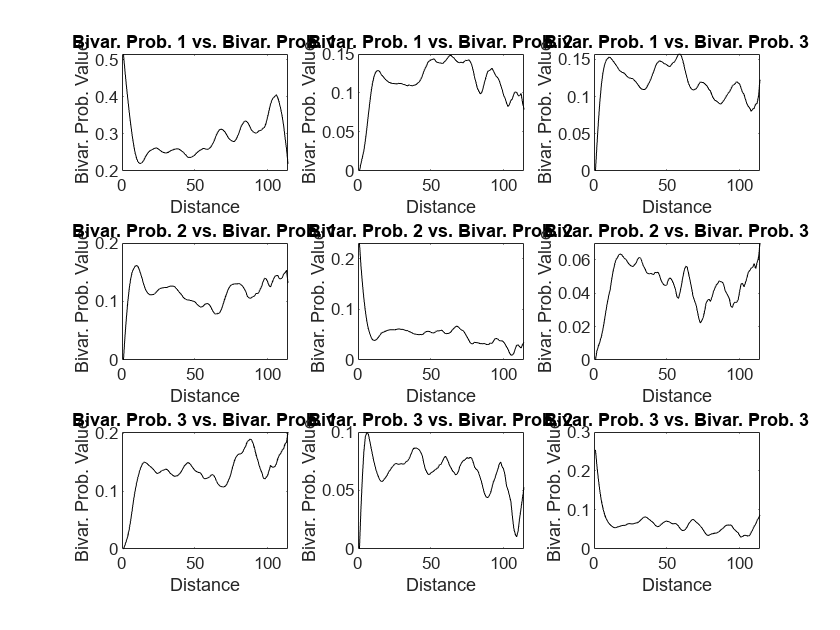


% Plot the bivariate probabilities
figure(4) % Use the same figure for plotting bivariate probabilities.
for i = 1:3 % Loop through the first dimension (3 categories).
    for j = 1:3 % Loop through the second dimension (3 categories).
        subplot(3, 3, ((i-1)*3 + j)) % Create a subplot for each combination of categories.
        plot(gh{i, j}(nx:end, ny), '-k') % Plot the bivariate probability data.
        title(['Bivar. Prob. ' num2str(i) ' vs. Bivar. Prob. ' num2str(j)]); % Add title for clarity.
        xlabel('Distance'); % Label the x-axis.
        ylabel('Bivar. Prob. Value'); % Label the y-axis.
    end
end

## Non-ergodic transiograms

This section focuses on computing non-ergodic transiograms for the categorical data obtained from the sand dune training image. The process begins by specifying that the data is categorical (`categ = 1`). The display flag is activated (`display = 1`), which allows for visual output of the results. The `icode` is set to 7, indicating that the function will compute non-ergodic transiograms.

To visualize the non-ergodic transiograms, the code creates a new figure (figure 5) where a nested loop iterates through all combinations of the three categories. For each combination, a subplot is generated to display the corresponding non-ergodic transiogram data, plotted in black. This visualization facilitates the examination of spatial relationships and dependencies between different categorical classes, offering insights into the variability and interactions of the sand dune facies over the study area.

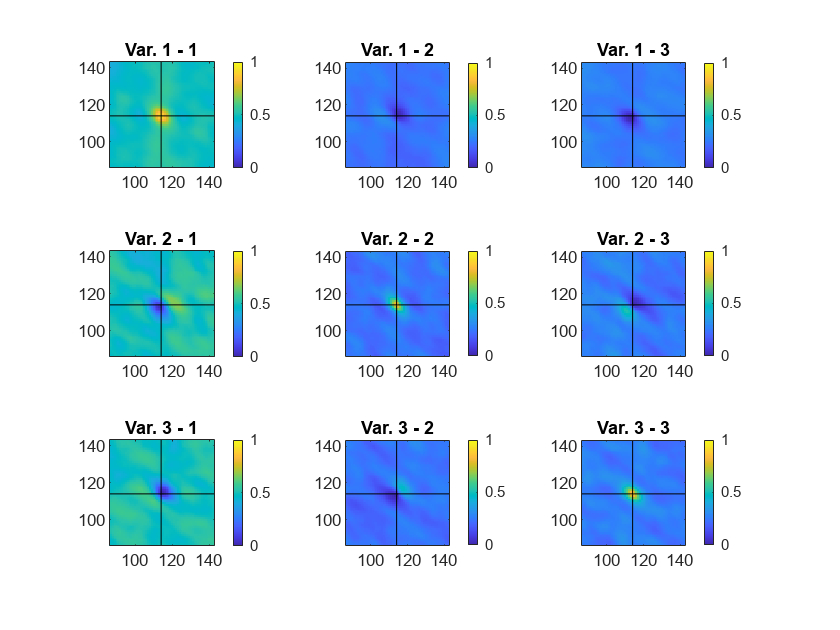

categ = 1; % Specify categorical data.
display = 1; % Set display flag to true for visualization.
icode = 7; % Set the code for computing non-ergodic transiograms.
[gh, nh] = GeoStatFFT(x0, Z, icode, categ, display); % Compute non-ergodic transiograms using GeoStatFFT.

% Plot the non-ergodic transiograms
figure(5) % Use the same figure for plotting non-ergodic transiograms.
for i = 1:3 % Loop through the first dimension (3 categories).
    for j = 1:3 % Loop through the second dimension (3 categories).
        subplot(3, 3, ((i-1)*3 + j)) % Create a subplot for each combination of categories.
        plot(gh{i, j}(nx:end, ny), '-k') % Plot the non-ergodic transiogram data.
    end
end

## Third-order cumulant of a zero mean random function

This section computes the third-order cumulant for a zero-mean random function, focusing on capturing the relationships between transitions of categorical data in two dimensions. To account for shifts in the data, the code is expanded by including the shift vector. In this context, `icode` is set to 11, and the shift vector is specified as `h2 = [5, 0]`, indicating the magnitude and direction of the shift.

Several figures are generated to explore different shift scenarios. The first figure (figure 21) displays the initial computation of transition occurrences using the specified shift. The code is updated for subsequent calculations, with each iteration generating a new figure for additional transition occurrences based on varying shift parameters. Specifically, figure 22 uses `icode = [11 5 5]`, figure 23 employs `icode = [11 0 5]`, and figure 24 utilizes `icode = [11 -5 5]`.

Each plot provides insights into the third-order cumulant's structure, allowing for a deeper understanding of the spatial interactions and dependencies present within the categorical data of the sand dune training image. This analysis is crucial for capturing non-linear relationships that may exist among different categories within the data.

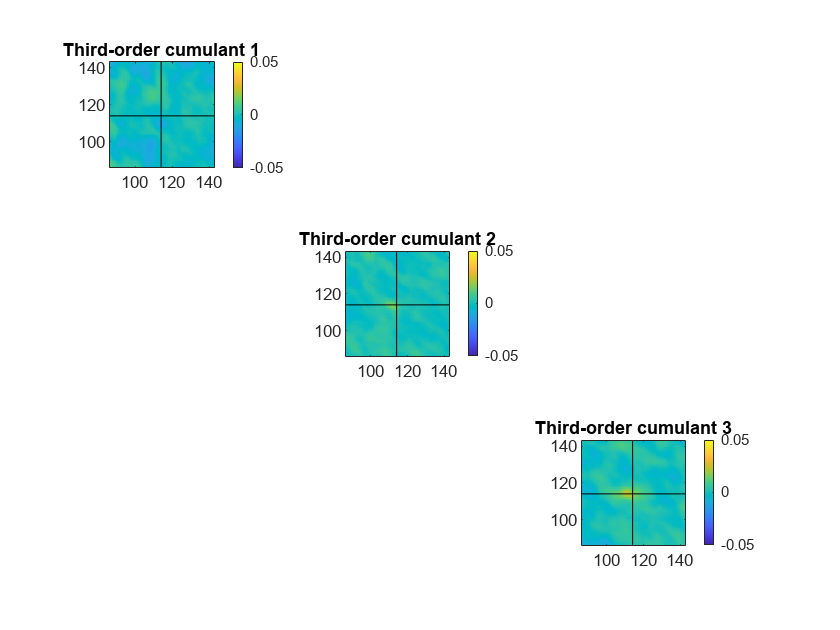

categ = 1; % Specify categorical data.
display = 1; % Set display flag to true for visualization.
icode = [11 5 0]; % Set code for computing transition occurrences.
figure(21) % Create a new figure for TOC.
[gh, nh] = GeoStatFFT(x0, Z, icode, categ, display); % Compute transition occurrences using GeoStatFFT.

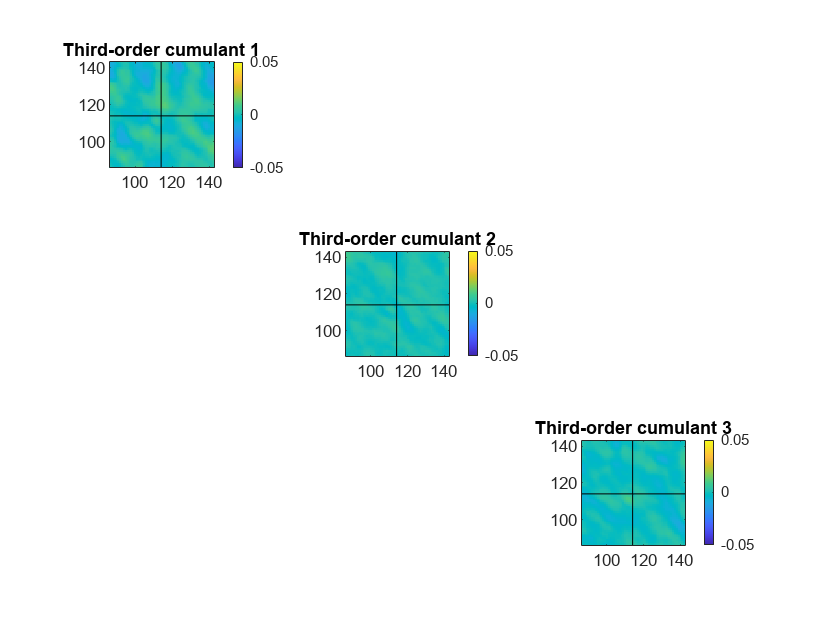


% Plot additional vector
icode = [11 5 5]; % Update the code for another transition occurrence calculation.
figure(22) % Create a new figure for the updated TOC.
[gh, nh] = GeoStatFFT(x0, Z, icode, categ, display); % Compute the updated transition occurrences.

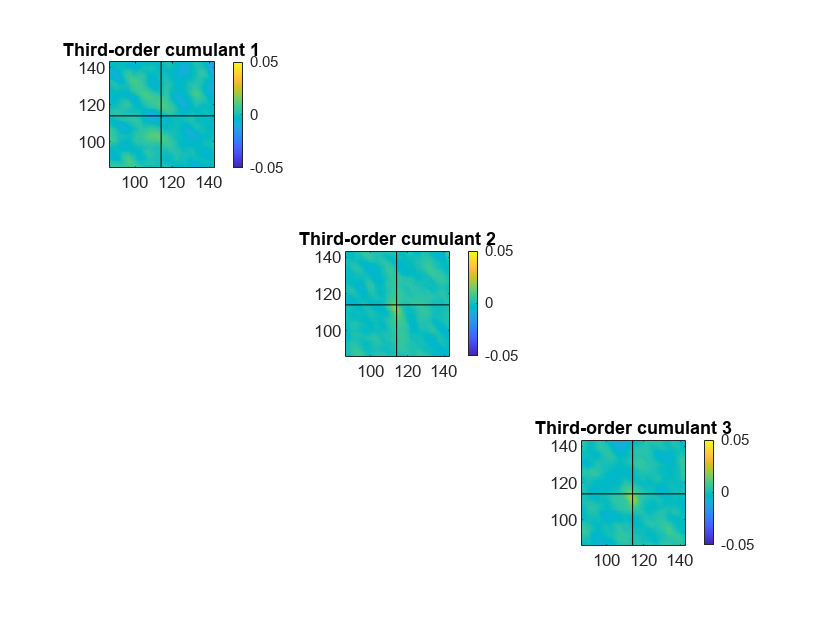


icode = [11 0 5]; % Set the code for yet another transition occurrence calculation.
figure(23) % Create a new figure for the next TOC.
[gh, nh] = GeoStatFFT(x0, Z, icode, categ, display); % Compute the next transition occurrences.

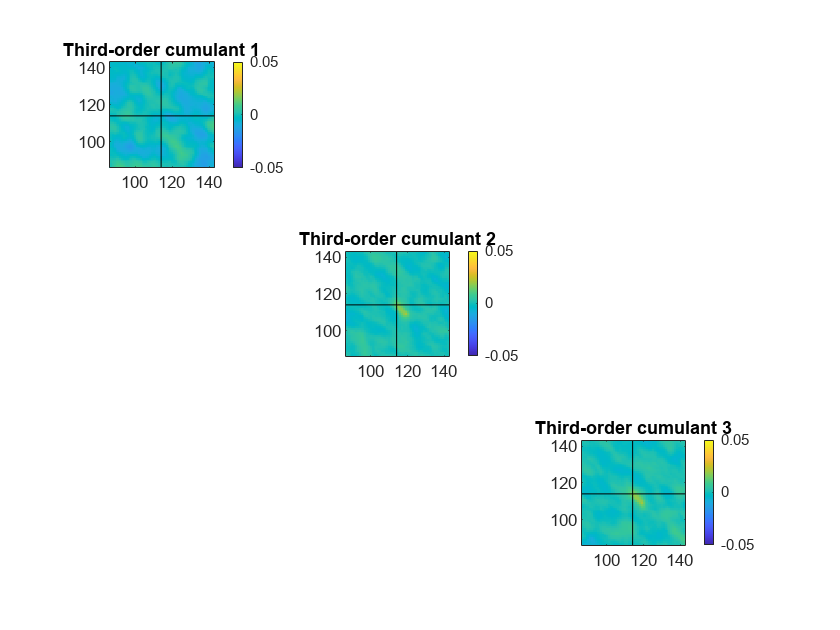


icode = [11 -5 5]; % Set the code for another transition occurrence calculation.
figure(24) % Create a new figure for this TOC.
[gh, nh] = GeoStatFFT(x0, Z, icode, categ, display); % Compute the final transition occurrences.